# Load and play voice signals

[sig1, fs1] = audioread('beep-02.wav');
[sig2, fs2] = audioread('beep-07a.wav');
[sig3, fs3] = audioread('beep-10.wav');

## Resample signals to a common sampling rate

common_fs = 44100; % Define a common sampling rate
sig1 = resample(sig1, common_fs, fs1);
sig2 = resample(sig2, common_fs, fs2);
sig3 = resample(sig3, common_fs, fs3);

fs1 = common_fs; fs2 = common_fs; fs3 = common_fs;

## Ensure all signals have the same length

min_length = min([length(sig1), length(sig2), length(sig3)]);
sig1 = sig1(1:min_length);
sig2 = sig2(1:min_length);
sig3 = sig3(1:min_length);

## playback

sound(sig1, fs1); pause(2);

sound(sig2, fs2); pause(2);

sound(sig3, fs3); pause(2);

## plot signals

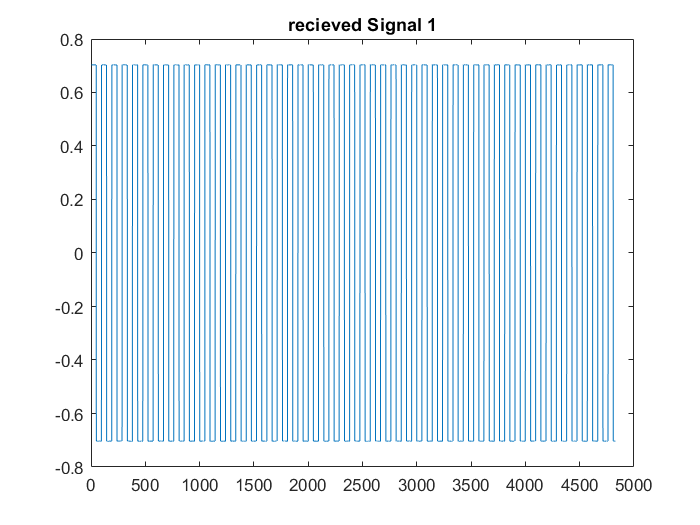

figure; plot(sig1); title('recieved Signal 1');

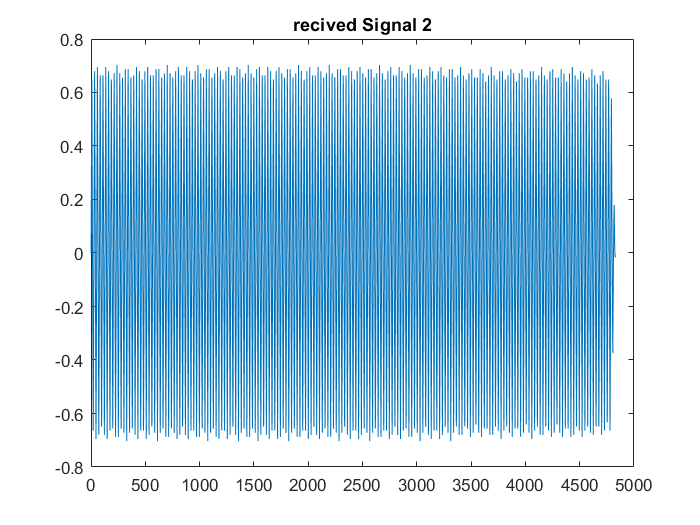

figure; plot(sig2); title('recived Signal 2');

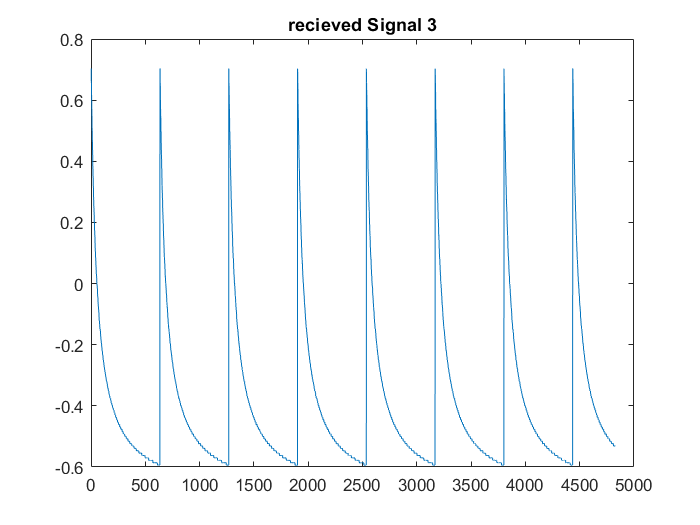

figure; plot(sig3); title('recieved Signal 3');

## Spectral analysis

fft_sig1 = abs(fft(sig1));
fft_sig2 = abs(fft(sig2));
fft_sig3 = abs(fft(sig3));

## plot spectrum

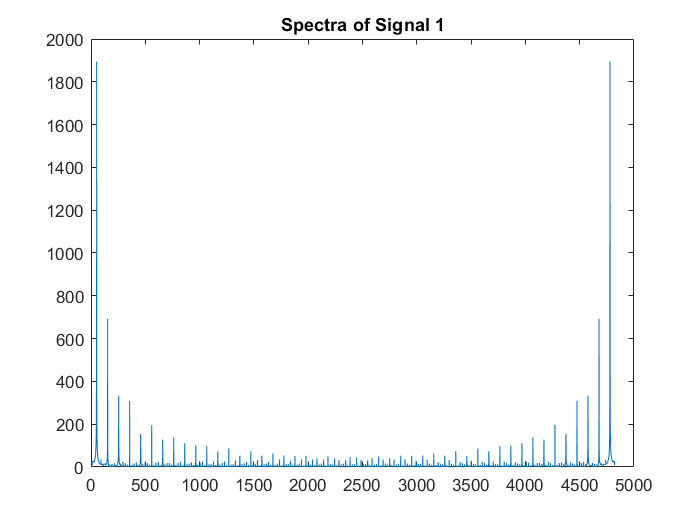

figure; plot(fft_sig1); title('Spectra of Signal 1');

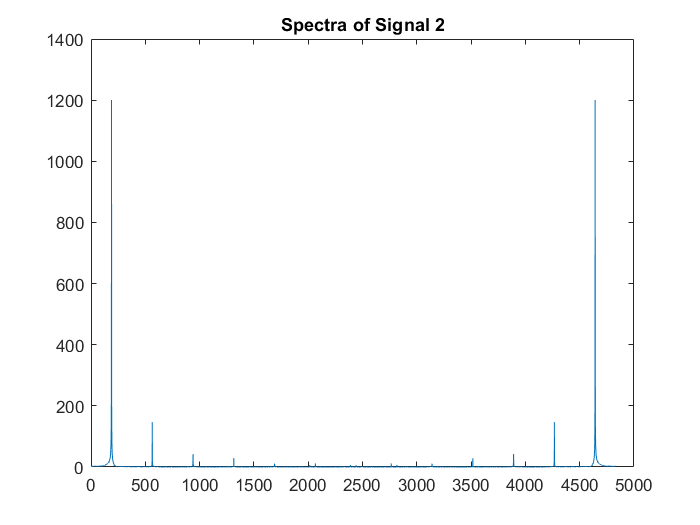

figure; plot(fft_sig2); title('Spectra of Signal 2');

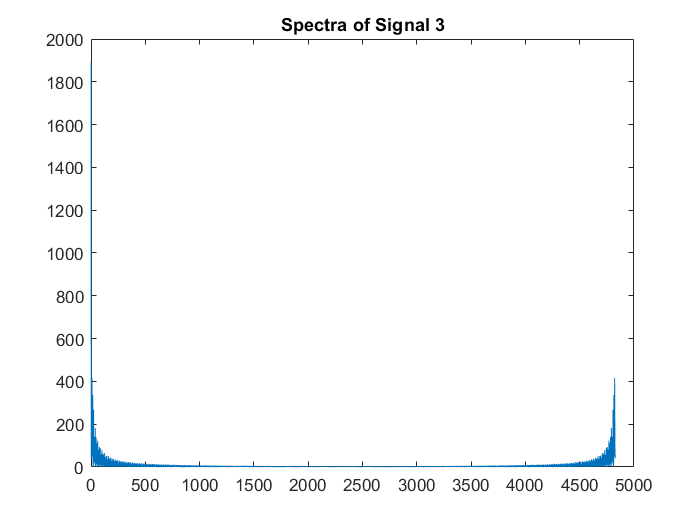

figure; plot(fft_sig3); title('Spectra of Signal 3');

## Low Pass Filtering

fc = 5000; % Cutoff frequency (Hz)
sig1_filt = lowpass(sig1, fc, fs1);
sig2_filt = lowpass(sig2, fc, fs2);
sig3_filt = lowpass(sig3, fc, fs3);

## filtered plot

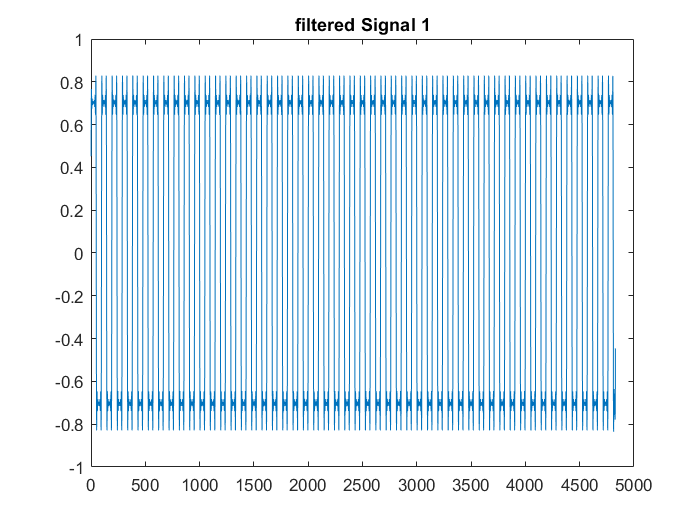

figure; plot(sig1_filt); title('filtered Signal 1');

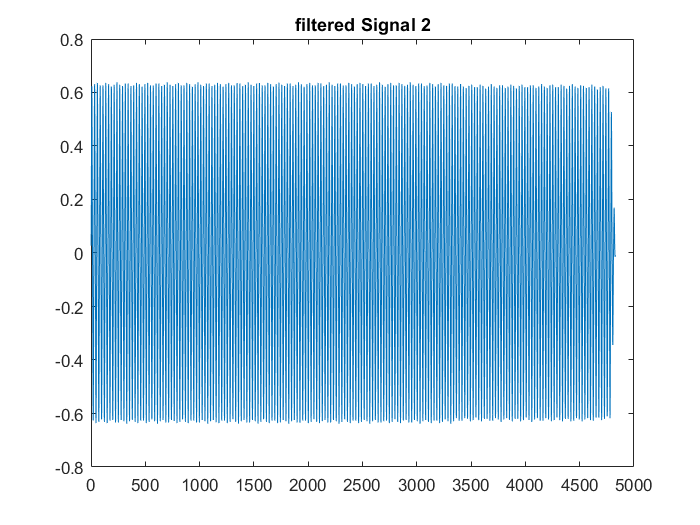

figure; plot(sig2_filt); title('filtered Signal 2');

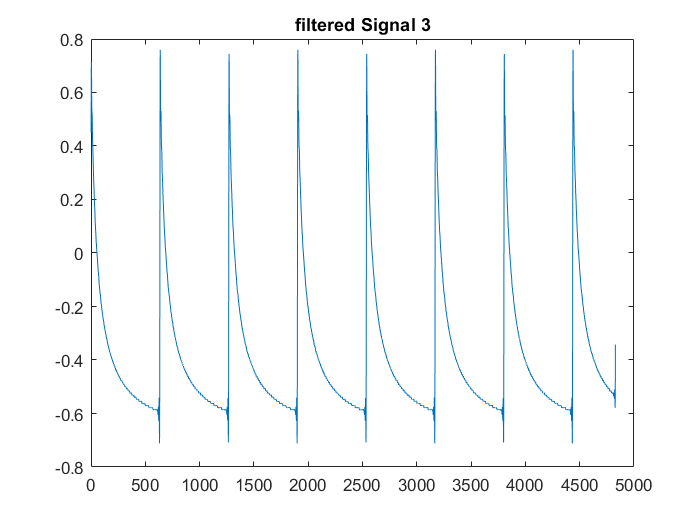

figure; plot(sig3_filt); title('filtered Signal 3');

## Modulation

t = (0:length(sig1_filt)-1) / fs1; % Time vector
carrier1 = cos(2*pi*1000*t)';
carrier2 = cos(2*pi*2000*t)';
carrier3 = cos(2*pi*3000*t)';

mod_sig1 = sig1_filt .* carrier1;
mod_sig2 = sig2_filt .* carrier2;
mod_sig3 = sig3_filt .* carrier3;

## modulated plot

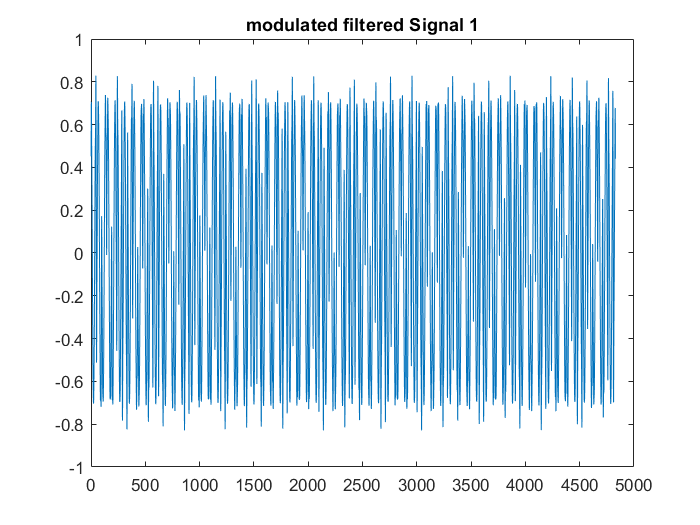

figure; plot(mod_sig1); title('modulated filtered Signal 1');

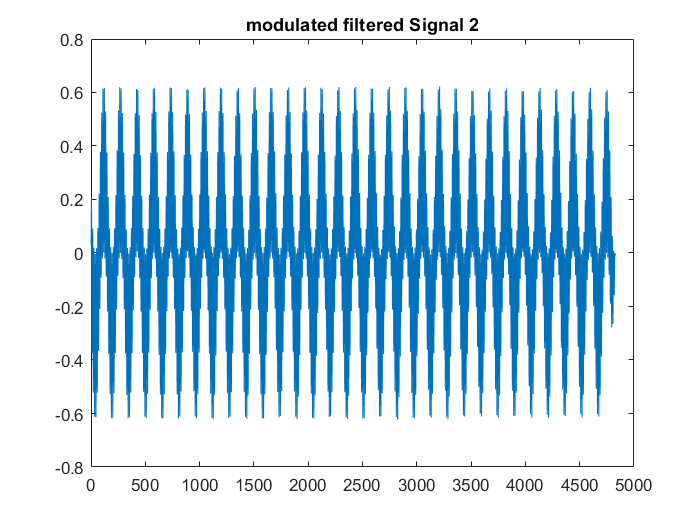

figure; plot(mod_sig2); title('modulated filtered Signal 2');

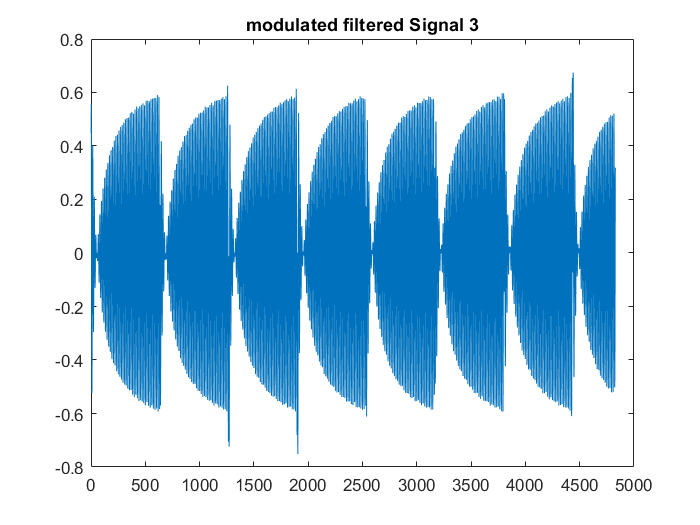

figure; plot(mod_sig3); title('modulated filtered Signal 3');

## Multiplexing

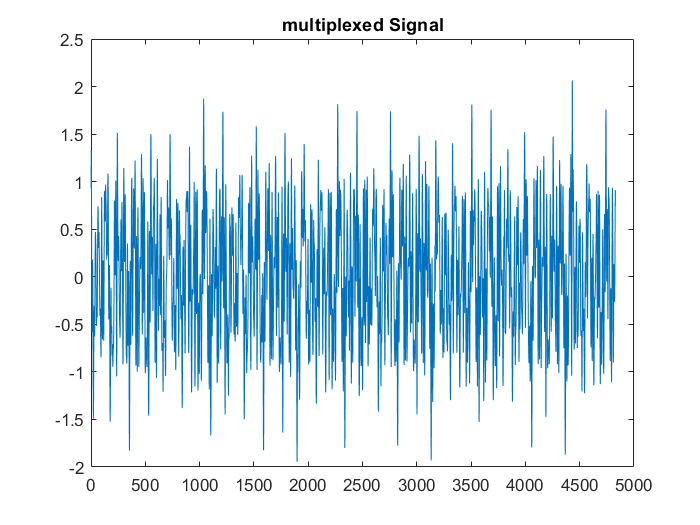

mux_sig = mod_sig1 + mod_sig2 + mod_sig3;

figure; plot(mux_sig); title('multiplexed Signal');

## Adding noise

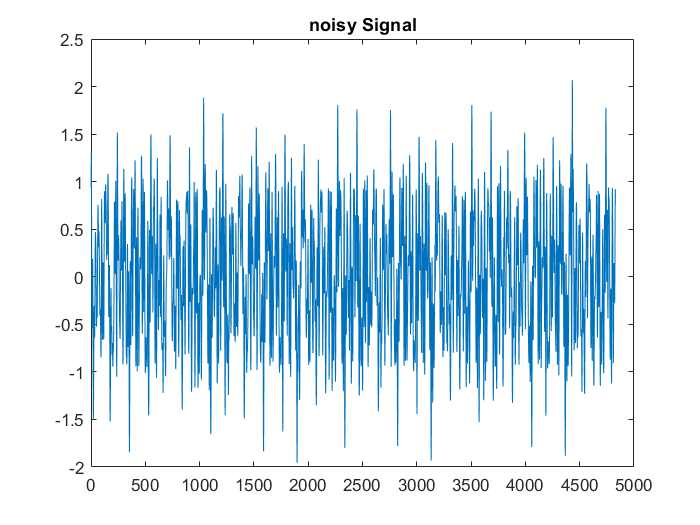

noise =  0.01 * randn(size(mux_sig));
noisy_sig = mux_sig +noise;
figure; plot(noisy_sig); title('noisy Signal');

## Demultiplexing and demodulation

demod_sig1 = noisy_sig .* carrier1;
demod_sig2 = noisy_sig .* carrier2;
demod_sig3 = noisy_sig .* carrier3;

## plot

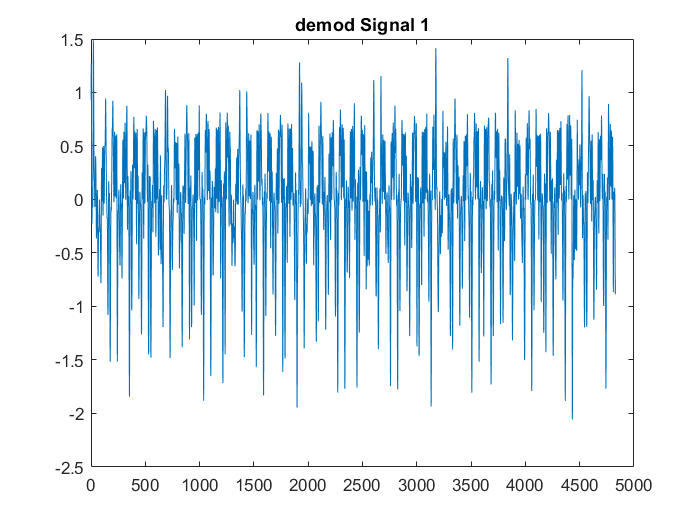

figure; plot(demod_sig1); title('demod Signal 1');

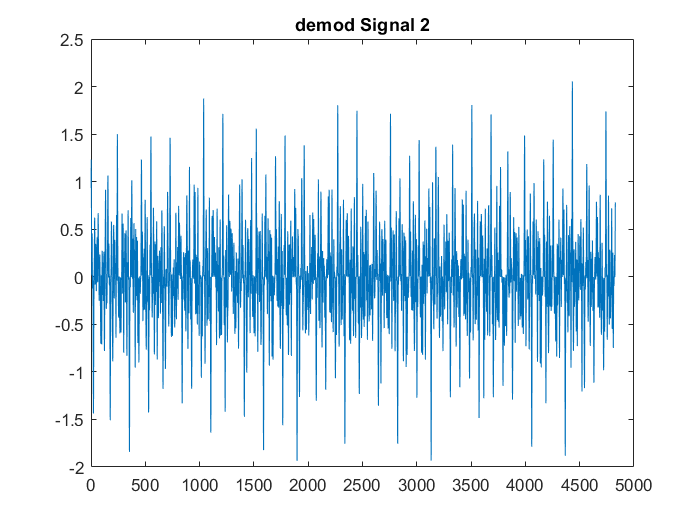

figure; plot(demod_sig2); title('demod Signal 2');

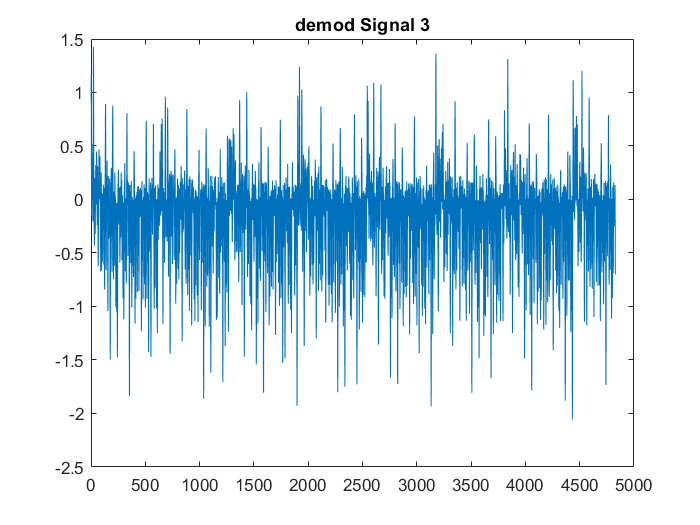

figure; plot(demod_sig3); title('demod Signal 3');

## lowpass

demod_sig1 = lowpass(demod_sig1, fc, fs1);
demod_sig2 = lowpass(demod_sig2, fc, fs2);
demod_sig3 = lowpass(demod_sig3, fc, fs3);

## plot

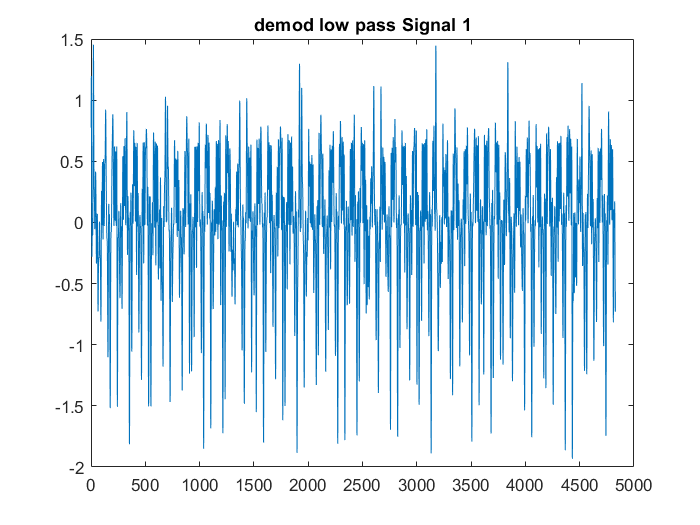

figure; plot(demod_sig1); title('demod low pass Signal 1');

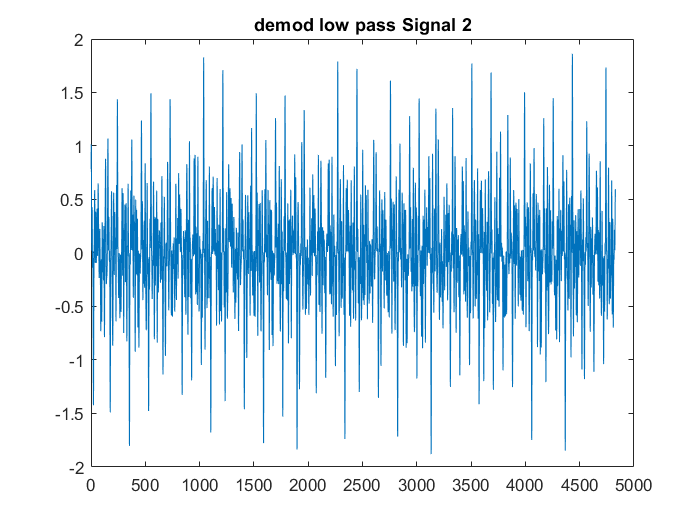

figure; plot(demod_sig2); title('demod low pass Signal 2');

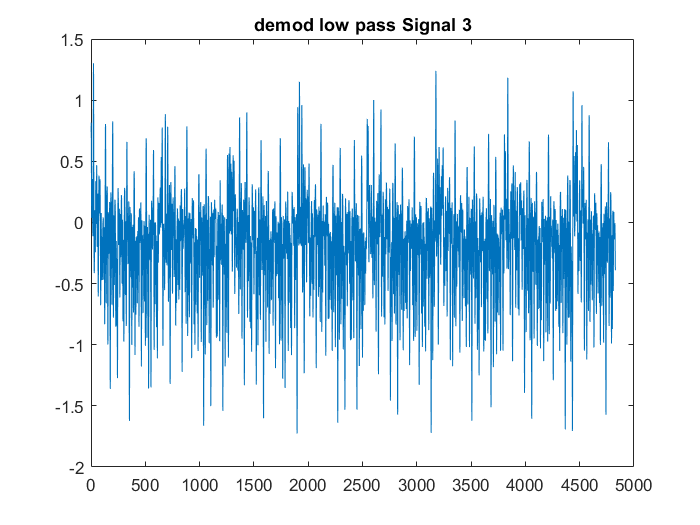

figure; plot(demod_sig3); title('demod low pass Signal 3');

## Recovered signals

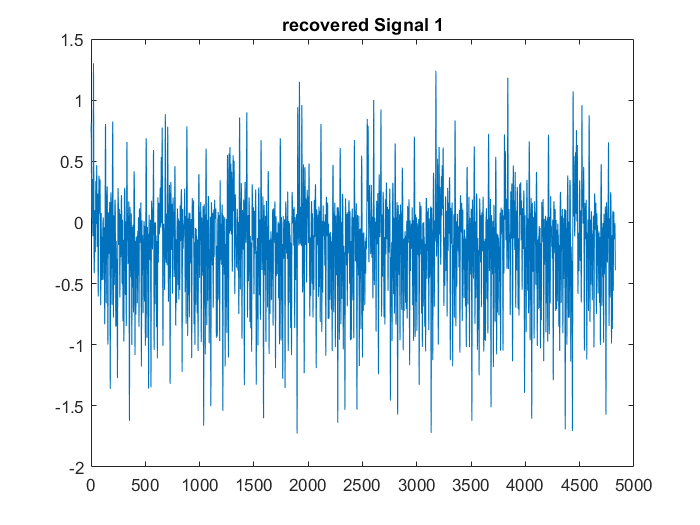

sound(demod_sig1, fs1); pause(2);
figure; plot(demod_sig3); title('recovered Signal 1');

## 2

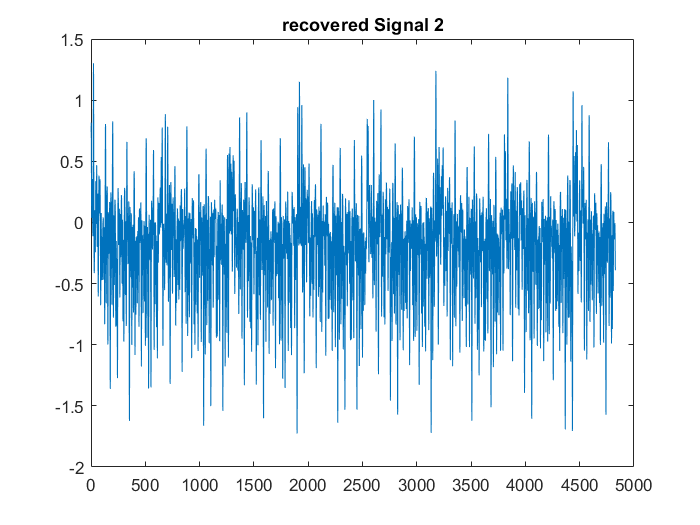

sound(demod_sig2, fs2); pause(2);
figure; plot(demod_sig3); title('recovered Signal 2');

## 3

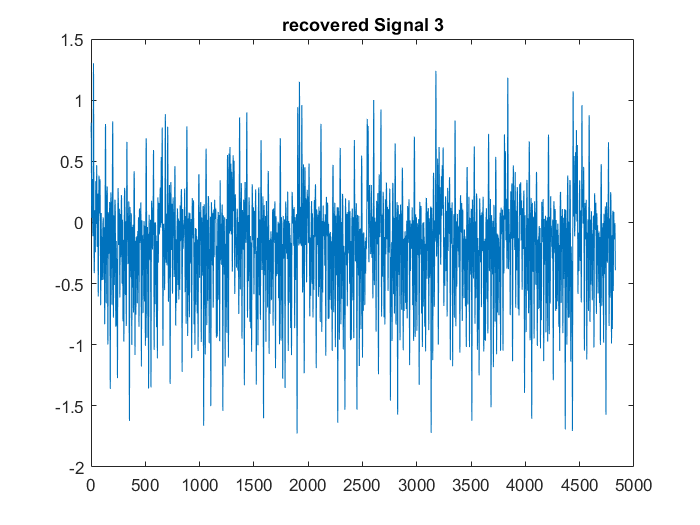

sound(demod_sig3, fs3); pause(2);
figure; plot(demod_sig3); title('recovered Signal 3');